# Test script for basic TANDEM-STRAIGHT analysis and synthesis

clear
%   Please use this in "cell mode"

## Initialize conditions        %条件を初期化

directoryBase = [pwd '/'];
filename_save = 'あらゆる現実・居酒屋';
filename_save2 = 'あらゆる現実・居酒屋';

% % directoryBase = './強調音声/強調音声＿動的＿D/閾値_0.125/mode_1/';                        %処理する音声の場所                    %処理する音声の名前
% % filename_save = '強調音声_動的_D［n=48, weight=10, range=2500-3500, mode=1, threshold=0.125］【sample1-2-1】';
% % filename_save2 = '強調音声\_動的\_D［n=48, weight=10, range=2500-3500, mode=1, threshold=0.125］【sample1-2-1】';

fileName = [filename_save '.wav'];

noisy = 0; % If the speech material consists of low frequency noise, set this vaviable 1;
plotFigures = 1; % If you do not need plots, set this variable 0.

## Read speech data from a file   %ファイルから音声データを読み取る

[x,fs] = audioread([directoryBase fileName]);

x = x(:,1); %   Make sure it is a comum vector.
soundsc(x,fs) % Playback sound

## Extract source information    %ソース情報を抽出する

## Extract spectral informatiopn    %スペクトル情報を抽出する

filename_straight = ['STRAIGHT_ver2【' filename_save '】.mat'];

%matファイルの有無による処理
if (exist(filename_straight,'file') == 0)
    disp('matファイルが見つかりませんでした。');
    
   [f, rc, q, fs] = getstraight_ver3(x, fs, noisy);           %STRAIGHTスペクトル抽出部分の関数化
    save(filename_straight, 'f', 'rc', 'q', 'fs');            %STRAIGHTスペクトルのmatファイルを作成
else
    disp('matファイルが見つかりました。');
    file = load(filename_straight);
    
    f = file.f;
    fs = file.fs;
    rc = file.rc;
    q = file.q;
end

matファイルが見つかりました。


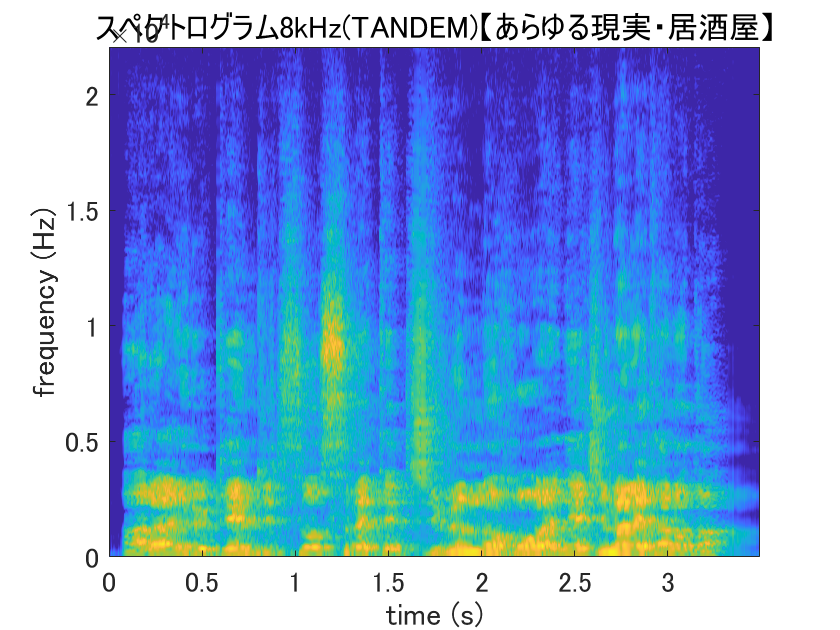

sgramSTRAIGHT = 10*log10(f.spectrogramSTRAIGHT);
maxLevel = max(max(sgramSTRAIGHT));
figure;
imagesc([0 f.temporalPositions(end)],[0 fs/2],max(maxLevel-80,sgramSTRAIGHT));
axis('xy')
set(gca,'fontsize',14);
xlabel('time (s)')
ylabel('frequency (Hz)');
% str = ['スペクトログラム(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
str = ['スペクトログラム8kHz(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル

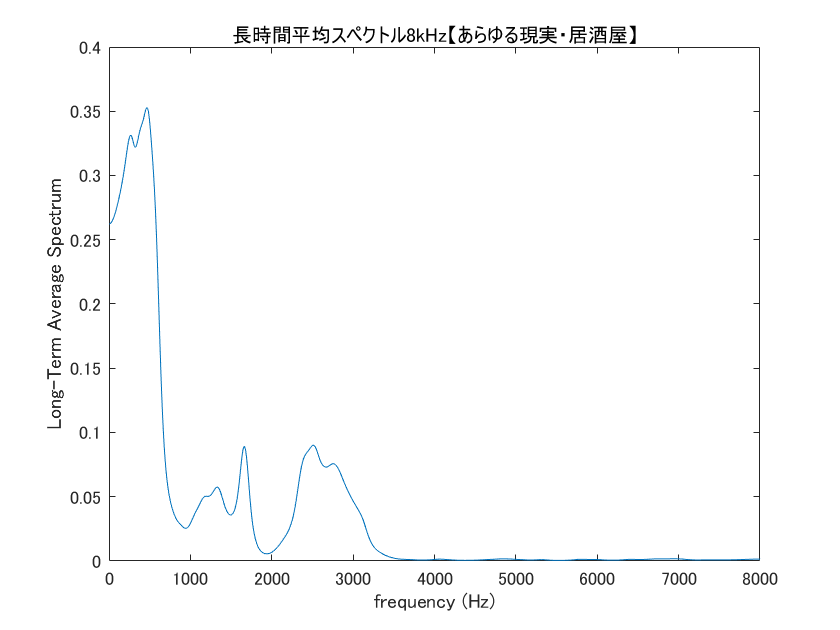

% xlim([0 4.0]);                                         %x軸の値の範囲
% ylim([0 8000]);                                        %y軸の値の範囲
% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

f0raw = rc.f0';
n3sgram = sqrt(f.spectrogramSTRAIGHT);    %パワースペクトルを振幅スペクトルに変更

% save(filename_save, 'f0raw', 'fs', 'n3sgram');      %matファイルの作成（動的特徴量用）

%%長時間平均スペクトル
column_size = size(f.spectrogramSTRAIGHT, 2);      %列の大きさ
ltas = sum(f.spectrogramSTRAIGHT, 2) ./ column_size;    %行方向の平均
fftl = (length(ltas)-1)*2;                         %fftlを新たに定義
x = ((0:fftl/2)*fs/fftl)';                         %横軸をHzで表示
ltas_decibel = 10 * log10(ltas);                   %dB値に変換

plot(x, ltas); 
xlabel('frequency (Hz)');
ylabel('Long-Term Average Spectrum');
str1 = ['長時間平均スペクトル8kHz【' filename_save '】'];          %動的にファイル名を作成
str2 = ['長時間平均スペクトル8kHz【' filename_save2 '】'];          %動的にファイル名を作成
title(str2);                                            %タイトル                       
xlim([0 8000]); 

% print(str1, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

plot(x, ltas_decibel); 
% xlabel('frequency (Hz)');
% ylabel('Long-Term Average Spectrum (dB)');
% str1 = ['長時間平均スペクトル(dB)8kHz【' filename_save '】'];          %動的にファイル名を作成
% str2 = ['長時間平均スペクトル(dB)8kHz【' filename_save2 '】'];          %動的にファイル名を作成
% % xticks([0 5 10]);
% % xticklabels({'x = 0','x = 5','x = 10'});
set(gca,'FontSize',14);
xticks(0:1000:8000);
xtickangle(45);
xlabel('frequency (Hz)', 'fontsize', 18);
ylabel('Long-Term Average Spectrum (dB)', 'fontsize', 18);
str = '文＿とても通る声','FontSize',14; 

str = '文＿とても通る声'

ans = 'FontSize'

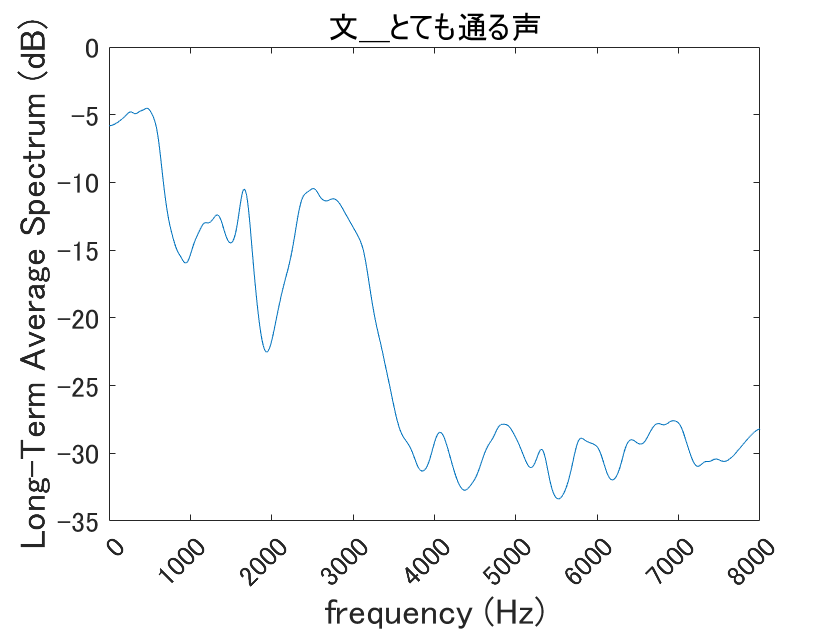

title(str);
% title(str2);                                            %タイトル                       
xlim([0 8000]);

% ylim([-60 -10]);
str = ['長時間平均スペクトル(dB)8kHz(論文用)【' filename_save '】'];
% print(str1, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

% s = exTandemSTRAIGHTsynthNx(q,f)
% sound(s.synthesisOut/max(abs(s.synthesisOut))*0.8,fs) % old implementation

% s2 = exGeneralSTRAIGHTsynthesisR2(q,f) % new implementation
% sound(s2.synthesisOut/max(abs(s2.synthesisOut))*0.8,fs)